# START HYPERPARAMS

slope_ratio_threshold = 1; % hyperparam used to detect tilted peaks

% for fDOM event separation
fDOM_PKThreshold = 3; % peak threshold for runoff events
fDOM_ReRa = 0.9; % return ratio
fDOM_start_slope = .001; % used to cut off 'flat' event starts and ends
fDOM_end_slope = .0001; 
fDOM_smoothing_passes = 4; % number of times data is smoothed with an averaging filter of window size 3
fDOM_basewidth_threshold = 10; % threshold hyperparam for detecting sharp peaks anomalies
fDOM_sharp_upward_peak_magnitude_threshold = 100; % when do we consider a sharp upward peak to be an anomaly 
fDOM_sharp_downward_peak_magnitude_threshold = 100; % when do we consider a sharp downward peak to be an anomlay
single_datapoint_basewidth_threshold = 5; 
single_datapoint_peak_magnitude_threshold = 100; % when do we consider a 'single point event' to be an anomaly

% for removal of negative fDOM spikes
min_flipped_height = 103;

% for stage event separation
stage_PKThreshold = 0.02;
stage_ReRa = 0.6;
stage_start_slope = .001;
stage_end_slope = .0001;
stage_smoothing_passes = 4;

% for turbidity event separation
turb_PKThreshold = 15;
turb_ReRa = 0.6;
turb_start_slope = .001;
turb_end_slope = .0001;
turb_smoothing_passes = 4;
turb_basewidth_threshold = 10; 
turb_sharp_upward_peak_magnitude_threshold = 1000;
turb_sharp_downward_peak_magnitude_threshold = 1000; 


## START LOADING DATA

% add function folder to MATLAB search path
addpath('HydRun-master/HydRun_Functions'); 
addpath('aux_functions');

% loading the matlab data: time series of streamflow and precip (rainfall)
load('../Data/converted_data/fDOM_raw_10.1.12-9.4.20.mat', 'fDOM_raw'); 
% load('converted_data/stage_corrected_9.30.16-7.13.20.mat', 'stage');
load('../Data/converted_data/stage_10.1.12-7.13.20.mat', 'stage_all');
load('../Data/converted_data/turbidity_corrected_10.1.12-9.4.20.mat', 'turb');
load('../Data/converted_data/fDOM_corrected_10.1.12-9.4.20.mat', 'fDOM_corrected');
%fDOM_corrected(:,1) = fDOM_corrected(:,1) + 0.224 * 1; % shift timeframe forward 15 minutes

% Trim data to within range of smallest dataset: 10.1.12 to 7.13.20 
stage = stage_all;
end_time = stage(end,1);
start_time = stage(1,1);
turb = trim_timeseries(turb,start_time,end_time);
fDOM_raw = trim_timeseries(fDOM_raw, start_time, end_time);
fDOM_corrected = trim_timeseries(fDOM_corrected, start_time, end_time);


## Write data out to .mat for later anomaly anotation

% save_timeseries_as_datetime(fDOM_raw, "data_annotating/non_annotated_csv/fDOM_raw_10.1.12-7.13.20.mat");
% save_timeseries_as_datetime(fDOM_corrected,"data_annotating/non_annotated_csv/fDOM_corrected_10.1.12-7.13.20.mat");
% save_timeseries_as_datetime(stage,"data_anotating/non_annotated_csv/stage_10.1.12-7.13.20.mat");
% save_timeseries_as_datetime(turb,"data_annotating/non_annotated_csv/turb_10.1.12-7.13.20.mat");
% fDOM_raw_csvfile = fopen('data_annotating/non_annotated_csv/fDOM_raw_10.1.12-7.13.20.txt','w+')
% for i=1:length(fDOM_raw)
%     time = datetime(fDOM_raw(i,1),'convertfrom','juliandate');
%     fprintf(fDOM_raw_csvfile,'%s,%s\r\n',time, fDOM_raw(i,2));
% end
% fclose(fDOM_raw_csvfile);
% 
% fDOM_corrected_csvfile = fopen('data_annotating/non_annotated_csv/fDOM_corrected_10.1.12-7.13.20.txt','w+')
% for i=1:length(fDOM_corrected)
%     time = datetime(fDOM_corrected(i,1),'convertfrom','juliandate');
%     fprintf(fDOM_corrected_csvfile,'%s,%s\r\n', time, fDOM_corrected(i,2));
% end
% fclose(fDOM_corrected_csvfile);
% 
 turb_csvfile = fopen('data_annotating/non_formatted/turb_10.1.12-7.13.20.txt','w+')
 for i=1:length(turb)
     time = datetime(turb(i,1),'convertfrom','juliandate');
     fprintf(turb_csvfile,'%s,%s\r\n',time, turb(i,2));
 end
 fclose(turb_csvfile);
% 
% stage_csvfile = fopen('data_annotating/non_annotated_csv/stage_10.1.12-7.13.20.txt','w+')
% for i=1:length(stage)
%     time = datetime(stage(i,1),'convertfrom','juliandate');
%     fprintf(stage_csvfile,'%s,%s\r\n',time, stage(i,2));
% end
% fclose(stage_csvfile);


## START PROCESSING/ DESPIKING

## Extract Events From All Timeseries


% this extracts events for stage
[stage_events, num_stage_events] = extractrunoff(stage, stage_PKThreshold,stage_ReRa, ...
    stage_start_slope, stage_end_slope, stage_smoothing_passes);

% this extracts events for turbidity
[turb_events, num_turb_events] = extractrunoff(turb, turb_PKThreshold, turb_ReRa, ...
    turb_start_slope, turb_end_slope, turb_smoothing_passes);

% this extracts events for fDOM
[fDOM_events, num_fDOM_events] = extractrunoff(fDOM_raw, fDOM_PKThreshold, fDOM_ReRa, ...
    fDOM_start_slope, fDOM_end_slope, fDOM_smoothing_passes); 

## Plotting Events

%% Plotting fDOM Events
hold on;
title('fDOM Events');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'),fDOM_raw(:,2),'-','color','g');

for i=1:length(fDOM_events)
    event = fDOM_events{i};
    plot(datetime(event(:,1),'convertfrom','juliandate'), event(:,2),'o', 'color','m');
end
hold off;

% Plotting Stage Events
cla
hold on;
title('Stage Events');
plot(datetime(stage(:,1),'convertfrom','juliandate'),stage(:,2),'-','color','r');

for i=1:length(stage_events)
    event = stage_events{i};
    plot(datetime(event(:,1), 'convertfrom', 'juliandate'), event(:,2),'o','color','b');
end
hold off;

% Plot Turbidity Events 
hold on; 
title('Turbidity Events');
plot(datetime(turb(:,1),'ConvertFrom', 'juliandate'), turb(:,2),'-','color','c');
for i=1:length(turb_events)
    event = turb_events{i};
    plot(datetime(event(:,1), 'convertfrom', 'juliandate'), event(:,2),'o','color','k');
end
hold off;

## Anomaly Detection

hour = 0.0001140771161305; % an hour in julian year time. Used to detect 3 peak violations
hour = hour * 2;

## fDOM Anomalies

fDOM_anomalies = fDOM_events; 
for i =1:num_fDOM_events
    
    % Track anomalies detected per event (could be more than one)
    single_data_point = false; 
    plummeting_peak = false;
    tilted_peak = false;
    three_peak_violation = false;
    
    turb_check = false; % used to track three peak violations
    stage_check = false;
    
    event = fDOM_events{i};
    fDOM_start = fDOM_events{i}(1);
    
    basewidth = length(fDOM_events{i}(:,1));
    
    % Detect Single Data Point % this does not work yet due to how events
    % are detected: I need to create a separate function for this
    if (basewidth < single_datapoint_basewidth_threshold) && (max(event(:,1)) > single_datapoint_peak_magnitude_threshold)
        single_data_point = true;
    end
    % Detect Plummeting Peak
    if basewidth < fDOM_basewidth_threshold && max(event(:,1)) > fDOM_sharp_upward_peak_magnitude_threshold
        plummeting_peak = true;
    end
    % Detect Tilted Peak
    if juliansloperatio(event) < slope_ratio_threshold
        tilted_peak = true;
    end
    % Detect Three Peak Violation
    for j = 1:num_turb_events
        turb_start = turb_events{j}(1);
        
        if turb_start > fDOM_start
            break
        elseif fDOM_start - turb_start < hour
            turb_check = true;
            break
        end
    end

    % stage
    for j = 1:num_stage_events
        stage_start = stage_events{j}(1);
        if stage_start > fDOM_start
            break
        elseif fDOM_start - stage_start < hour
            stage_check = true;
            break
        end
    end
    
    if ~stage_check || ~turb_check
       three_peak_violation = true;
    end
    
    fDOM_anomalies{i,2} = [single_data_point plummeting_peak tilted_peak three_peak_violation];
end

## Turbidity Anomalies

turb_anomalies = turb_events; 
for i=1:num_turb_events
    event = turb_events{i};
    basewidth = length(turb_events{i}(:,1));
    sharp_peak = false; 
    % Detect Plummeting Peak
    if basewidth < turb_basewidth_threshold && max(event(:,1)) > turb_sharp_upward_peak_magnitude_threshold
        sharp_peak = true;
    end
    turb_anomalies{i,2} = [sharp_peak];
end

length(stage_events)

## Correct fDOM. Currently - interpolating over basewidth anomalies


% This interpolates across sharp peaks and single point anomalies
fDOM_despiked = interp_flagged_events(fDOM_anomalies, length(fDOM_anomalies), fDOM_raw);
% this flips the fDOM upside down to get rid of negative spikes
flipped_fDOM = flip_tseries(fDOM_despiked);
[pks,locs,w,p] = findpeaks(flipped_fDOM(:,2),'MinPeakHeight',min_flipped_height);
fDOM_despiked = interp_tseries(fDOM_despiked, pks,locs,w,p);

## Correct Turbidity

% Implement similar despiking process as above
turb_despiked = turb; % placeholder operation to allow saving

## Save Corrected fDOM and Turbidity

fname = sprintf('%s_%s-%s.mat', 'corrected_data/fDOM','10.1.2012','7.13.20');
save(fname, "fDOM_despiked");
fname = sprintf('%s_%s-%s.mat', 'corrected_data/turbidity','10.1.2012','7.13.20');
save(fname, "turb_despiked");


## Save Anomalies Detected to CSV files

file3Peak = fopen('anomaly_data/datetime/three_peak_violation_datetime.txt','w+')
filePlummetingPeak = fopen('anomaly_data/datetime/plummeting_peak_datetime.txt','w+')
fileTiltedPeak = fopen('anomaly_data/datetime/tilted_peak_datetime.txt','w+')
fileSinglePoint = fopen('anomaly_data/datetime/single_data_point_datetime.txt','w+')
fileTurbSharpPeak = fopen('anomaly_data/datetime/turb_sharp_peak_datetime.txt','w+')

%fDOM anomalies
for i=1:length(fDOM_anomalies)
   anomaly = fDOM_anomalies{i,1};
   flags = fDOM_anomalies{i,2};
   anomalies_occured = flags(1) || flags(2) || flags(3) || flags(4);
   if anomalies_occured
       start_datetime = datetime(anomaly(1,1),'convertfrom','juliandate');
       end_datetime = datetime(anomaly(end,1),'convertfrom','juliandate');
       % Single Point
       if flags(1)
           fprintf(fileSinglePoint,'%s,%s,%s\r\n', 'single_data_point',start_datetime,end_datetime);
       end
       % Plummeting Peak
       if flags(2)
           fprintf(filePlummetingPeak,'%s,%s,%s\r\n','plummeting_peak',start_datetime,end_datetime);
       end
       % Tilted Peak
       if flags(3)
           fprintf(fileTiltedPeak,'%s,%s,%s\r\n','tilted_peak',start_datetime,end_datetime);
       end
       if flags(4)
           fprintf(file3Peak,'%s,%s,%s\r\n','three_peak_violation',start_datetime,end_datetime);
       end
   end
end
%Turbidty anomalies
for i=1:length(turb_anomalies)
    anomaly = turb_anomalies{i,1};
    flag = turb_anomalies{i,2};
    if flag
        start_datetime = datetime(anomaly(1,1),'convertfrom', 'juliandate');
        end_datetime = datetime(anomaly(end,1),'convertfrom','juliandate');
        fprintf(fileTurbSharpPeak,'%s,%s,%s\r\n','turb_sharp_peak',start_datetime, end_datetime);
    end
end


fclose(fileTurbSharpPeak); 
fclose(fileTiltedPeak);
fclose(file3Peak);
fclose(fileSinglePoint);
fclose(filePlummetingPeak);

% Sensor Drift (not yet implemented)


file3Peak = fopen('anomaly_data/julian_time/three_peak_violation_julian.txt','w+')
filePlummetingPeak = fopen('anomaly_data/julian_time/plummeting_peak_julian.txt','w+')
fileTiltedPeak = fopen('anomaly_data/julian_time/tilted_peak_julian.txt','w+')
fileSinglePoint = fopen('anomaly_data/julian_time/single_data_point_julian.txt','w+')
fileTurbSharpPeak = fopen('anomaly_data/julian_time/turb_sharp_peak_julian.txt','w+')

for i=1:length(fDOM_anomalies)
   anomaly = fDOM_anomalies{i,1};
   flags = fDOM_anomalies{i,2};
   anomalies_occured = flags(1) || flags(2) || flags(3) || flags(4);
   if anomalies_occured
       start_jul = anomaly(1,1);
       end_jul = anomaly(end,1);
       % Single Point
       if flags(1)
           fprintf(fileSinglePoint,'%s,%s,%s\r\n', 'single_data_point',start_jul,end_jul);
       end
       % Plummeting Peak
       if flags(2)
           fprintf(filePlummetingPeak,'%s,%s,%s\r\n','plummeting_peak',start_jul,end_jul);
       end
       % Tilted Peak
       if flags(3)
           fprintf(fileTiltedPeak,'%s,%s,%s\r\n','tilted_peak',start_jul,end_jul);
       end
       if flags(4)
           fprintf(file3Peak,'%s,%s,%s\r\n','three_peak_violation',start_jul,end_jul);
       end
   end
end

%Turbidty anomalies
for i=1:length(turb_anomalies)
    anomaly = turb_anomalies{i,1};
    flag = turb_anomalies{i,2};
    if flag
        start_jul = anomaly(1,1);
        end_jul = anomaly(end,1);
        fprintf(fileTurbSharpPeak,'%s,%s,%s\r\n','turb_sharp_peak',start_jul, end_jul);
    end
end

fclose(fileTurbSharpPeak); 
fclose(fileTiltedPeak);
fclose(file3Peak);
fclose(fileSinglePoint);
fclose(filePlummetingPeak);

## Plotting anomalies against non corrected data

% Tilted Peaks
clf('reset')
hold on;
title('fDOM: Tilted Peaks');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'),fDOM_raw(:,2),'-','color','b');

for i=1:length(fDOM_anomalies)
    anomaly = fDOM_anomalies{i,1};
    flags = fDOM_anomalies{i,2};
    if flags(3)
        plot(datetime(anomaly(:,1), 'convertfrom', 'juliandate'), anomaly(:,2),'o','color','r');
    end
end
hold off; 
clf

% Single Point Peaks
clf('reset')
hold on;
title('fDOM: Single Point Peaks');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'),fDOM_raw(:,2),'-','color','b');

for i=1:length(fDOM_anomalies)
    anomaly = fDOM_anomalies{i,1};
    flags = fDOM_anomalies{i,2};
    if flags(1)
        plot(datetime(anomaly(:,1), 'convertfrom', 'juliandate'), anomaly(:,2),'o','color','r');
    end
end
hold off; 
clf

% Sharp Peaks fDOM
clf('reset')
hold on;
title('fDOM: Sharp Peaks');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'),fDOM_raw(:,2),'-','color','b');

for i=1:length(fDOM_anomalies)
    anomaly = fDOM_anomalies{i,1};
    flags = fDOM_anomalies{i,2};
    if flags(2)
        plot(datetime(anomaly(:,1), 'convertfrom', 'juliandate'), anomaly(:,2),'o','color','r');
    end
end
hold off; 
clf 

% Sharp Peaks Turbidity
clf('reset')
hold on;
title('Turbidity: Sharp Peaks');
plot(datetime(turb(:,1),'convertfrom','juliandate'),turb(:,2),'-','color','b');

for i=1:length(turb_anomalies)
    anomaly = turb_anomalies{i,1};
    flag = turb_anomalies{i,2};
    if flag
        plot(datetime(anomaly(:,1), 'convertfrom', 'juliandate'), anomaly(:,2),'o','color','r');
    end
end
hold off; 
clf 

% Three Peak Violations
% Single Point Peaks
clf('reset')
hold on;
title('fDOM: Three Peak Violation');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'),fDOM_raw(:,2),'-','color','b');

for i=1:length(fDOM_anomalies)
    anomaly = fDOM_anomalies{i,1};
    flags = fDOM_anomalies{i,2};
    if flags(4)
        plot(datetime(anomaly(:,1), 'convertfrom', 'juliandate'), anomaly(:,2),'o','color','r');
    end
end
hold off; 
clf

## START PLOTTING

% first subplot is raw vs despiked fDOM, with some types of spikes flagged
axs1 = subplot(3, 1, 1);
hold on;

title("Corrected vs Despiked fDOM")
% plot(fDOM_corrected(:,1), fDOM_corrected(:,2), '-c');
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'), fDOM_raw(:,2), '-', 'color', [1/178 1/100 1/5]);

% smoothed = smoothdata(fDOM_despiked(:,2),'movmedian',3);
plot(datetime(fDOM_despiked(:,1),'convertfrom','juliandate'), fDOM_despiked(:,2), 'color', [0.95 0.5 0.2]);
legend('Raw','Despiked');

% instead of removing some peaks (like tilted peaks), flag them here
for i = 1:num_fDOM_events
    runoff = fDOM_events{i};
    flag = fDOM_anomalies{i, 2};

    if strcmp(flag,'tilted')
        [peak, ipeak] = max(runoff(:, 2));
        plot(datetime(runoff(ipeak,1),'convertfrom','juliandate'), runoff(ipeak,2), '*b');
    end

end

% plot the HydRun event extracted stage for comparison
axs2 = subplot(3, 1, 2);

title('Stage ft')
plotrunoffevent(stage_events, stage); 

% plot the turbidity for comparison
axs3 = subplot(3, 1, 3);
title('Turb ft');
fig = plot(datetime(turb(:,1),'convertfrom','juliandate'), turb(:,2), '-',  'color', [1 0.5 0.5]);
legend('Turbidity');

linkaxes([axs1,axs2,axs3],'x');
hold off;

## Plot fDOM Raw vs Corrected

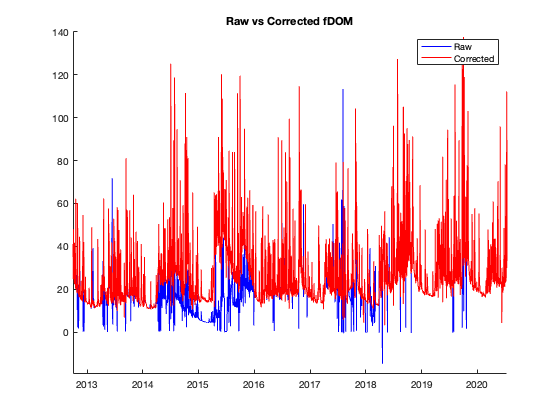


clf('reset')
clf
hold on;

title("Raw vs Corrected fDOM")
plot(datetime(fDOM_raw(:,1),'convertfrom','juliandate'), fDOM_raw(:,2), '-', 'color', [0 0 1]);
plot(datetime(fDOM_corrected(:,1),'convertfrom','juliandate'), fDOM_corrected(:,2), 'color', [1 0 0]);
legend('Raw','Corrected');
hold off; 